## **AOMIC Maximum Variance explained by all Communication/Similarity Measures **

This script computes the maximum variance in FC (node-specific) explained by any of the 8 coupling measures for each individual and averages node-specific values across all individuals. It also plots the respective figure in the paper. 

**Before running ths script:**

- Run AOMIC_compute_coupling_measures

**1) Save all coefficients per node (All_Nodes_complete but with R^2 Values)** 

1.1) Create a cell that contains for each subject a vector of 8 predictors for each node 

for i = 1:567
    x = final_r_all_AOMIC_567_new{i,2};
    for j = 1:358
    Node_all_baseline_best_measures_AOMIC_r2{i,j} = x(j,:);
    end
end


1.2) Create cell containing information about all subjects and coupling measures per node

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 567*8 matrix for each node)

n = size(Node_all_baseline_best_measures_AOMIC_r2,2);
All_Nodes_complete_baseline_best_measures_AOMIC_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_AOMIC_r2{j} = vertcat(Node_all_baseline_best_measures_AOMIC_r2{:,j});
end 

**2) Find the maximum value per row and keep it**

for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_AOMIC_r2{1,i};

    for p = 1:567
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        Max_values_individuals_AOMIC(1,p) = max_r2;

    end
    Mean_per_node = mean(Max_values_individuals_AOMIC);

    Mean_values_across_all_nodes{1,i} = Mean_per_node;
end


**3) Convert cell to mat **

Mean_values_across_all_nodes_mat = cell2mat(Mean_values_across_all_nodes)

Mean_values_across_all_nodes_mat =     0.2265    0.1356    0.1042    0.2557    0.2690    0.2242    0.2998    0.1546    0.1630    0.0768    0.0913    0.0833    0.2450    0.0784    0.0660    0.2246    0.1461    0.1914    0.2453    0.2780    0.2473    0.2271    0.1668    0.1225    0.0648    0.1160    0.0946    0.0754    0.0857    0.0842    0.1141    0.0542    0.0875    0.0890    0.1066    0.1128    0.0948    0.0981    0.1315    0.1491    0.1178    0.1327    0.1479    0.2008    0.1264    0.1161    0.1307    0.0715    0.0939    0.1046


**4) Insert a 0 at Node 120 & 300**

a = Mean_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_360 = a

Mean_values_across_all_nodes_mat_360 =     0.2265    0.1356    0.1042    0.2557    0.2690    0.2242    0.2998    0.1546    0.1630    0.0768    0.0913    0.0833    0.2450    0.0784    0.0660    0.2246    0.1461    0.1914    0.2453    0.2780    0.2473    0.2271    0.1668    0.1225    0.0648    0.1160    0.0946    0.0754    0.0857    0.0842    0.1141    0.0542    0.0875    0.0890    0.1066    0.1128    0.0948    0.0981    0.1315    0.1491    0.1178    0.1327    0.1479    0.2008    0.1264    0.1161    0.1307    0.0715    0.0939    0.1046


**5) Plot the Maximum Variance explained (across all subjects)**

Mean_values_across_all_nodes_mat_360(120) = NaN;
Mean_values_across_all_nodes_mat_360(300)= NaN;

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Mean_values_across_all_nodes_mat_360

dataVec =     0.2265    0.1356    0.1042    0.2557    0.2690    0.2242    0.2998    0.1546    0.1630    0.0768    0.0913    0.0833    0.2450    0.0784    0.0660    0.2246    0.1461    0.1914    0.2453    0.2780    0.2473    0.2271    0.1668    0.1225    0.0648    0.1160    0.0946    0.0754    0.0857    0.0842    0.1141    0.0542    0.0875    0.0890    0.1066    0.1128    0.0948    0.0981    0.1315    0.1491    0.1178    0.1327    0.1479    0.2008    0.1264    0.1161    0.1307    0.0715    0.0939    0.1046


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.3500]
    viewcMap: 1
     viewStr: 'all'


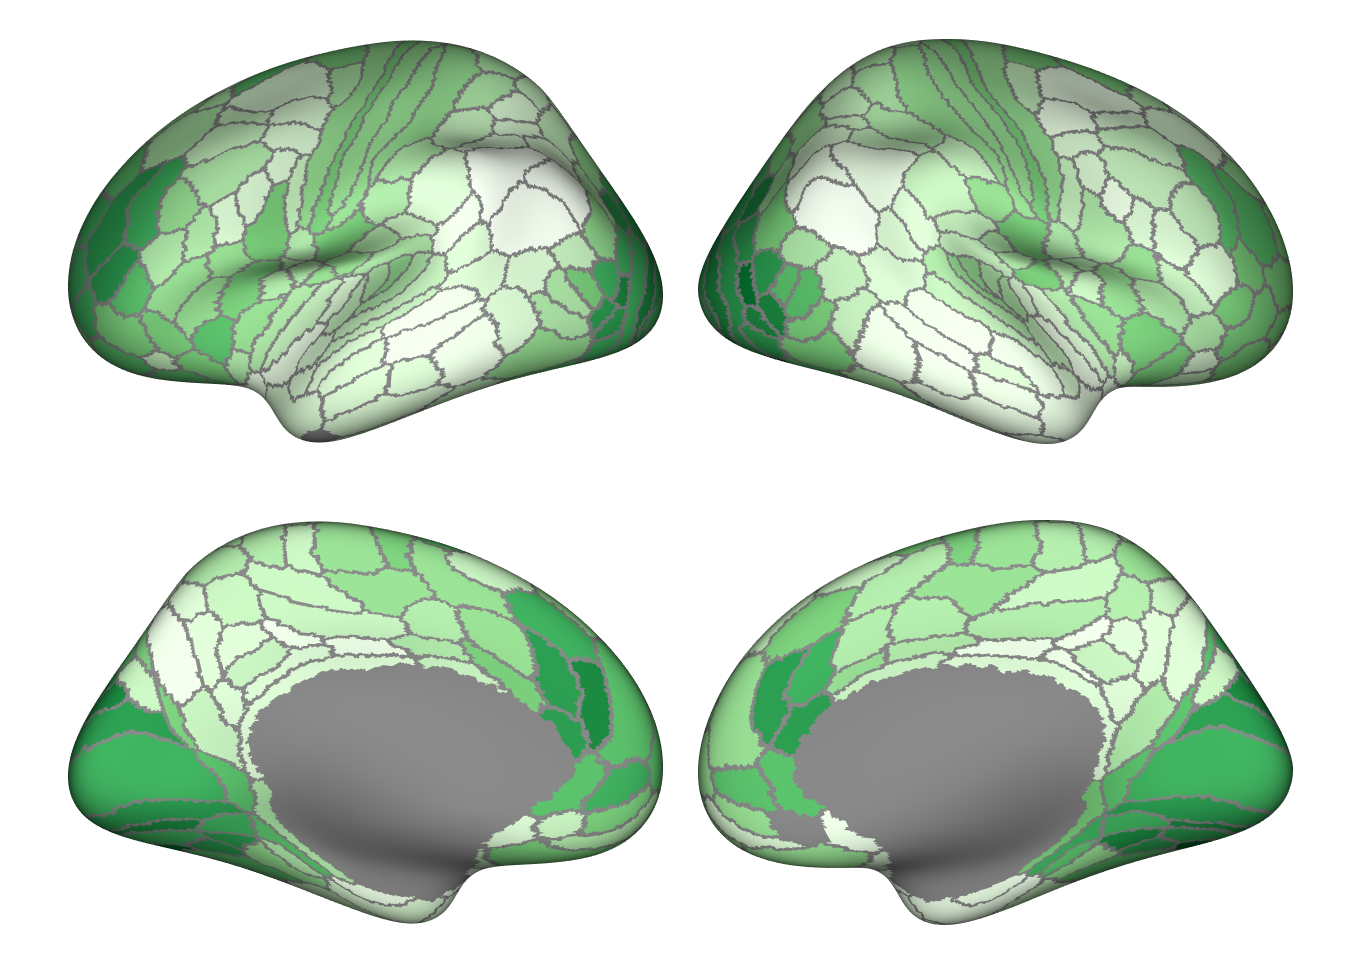

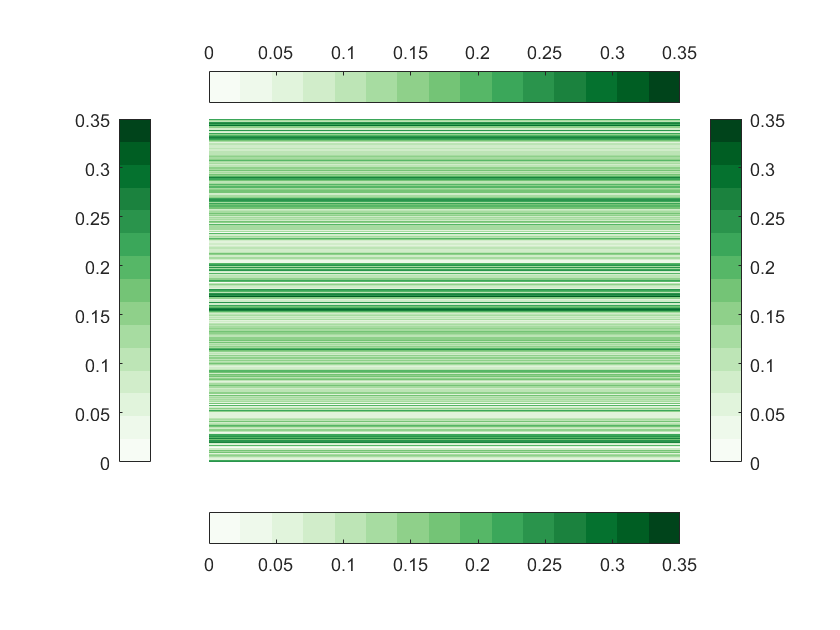

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


ans = 0.3055

parc_plot(surfStruct,annotMap,annotName,dataVec, 'cMap',brewermap(15,'Greens'),...
    'viewcMap',1, 'valRange', ([0 0.35]))     